## **Chaine QPSK**

**En bande passante**

%% Paramètres
Fs= 10000;
Rb= 2000;
Fc= 2000;
alpha= 0.35;
M= 4;
Rs = Rb/log2(M); %débit de symbole
Ns= Fs/Rs;
span= 8;
nb_bits_block= 6000;%plus on mets un chiffre grand mieux le grap final suivera 
% le théorique par contre moins le graph des xe sera lisible au premier abord 
N= span*Ns +1; %TP1 modulateur 4

%% Filtre RRC p(t)
h= rcosdesign(alpha, span, Ns, 'sqrt');
t0= N;

%% Boucle BER
tab_EbN0_dB = [0:8];
BER_simu= zeros(1, length(tab_EbN0_dB));
BER_theo= zeros(1, length(tab_EbN0_dB));

for k = 1:length(tab_EbN0_dB)
    EbN0_dB  = tab_EbN0_dB(k);
    EbN0_lin = 10^(EbN0_dB/10);

    nb_erreurs=0;
    compteur=0;

    while nb_erreurs<1000

        %% Génération des bits
        bits = randi([0,1], 1, nb_bits_block);

        %% Mapping : bits -> symboles complexes dk = Ik + j*Qk 
        % (voir schéma figure 1 les notations sont les mêmes)
        bits_reshape = reshape(bits, log2(M), []).';
        Ik=2*bits_reshape(:,1)-1;
        Qk=2*bits_reshape(:,2)-1;
        dk=(Ik+j*Qk)/sqrt(2);
        
        % Stockage des bits pour comparaison futur
        symbole_binaire=bits_reshape;

        %% Oversampling:sum dk*delta(t - kTs)
        diracs=kron(dk.',[1 zeros(1, Ns-1)]);

        %% Pulse Shaping: xe(t)=sum dk*h(t-kTs)
        xe=filter(h,1,diracs);
        xe=xe(:).';

        %% Frequency translation : x(t) = Re[xe(t) * exp(j2pi*fc*t)]
        t_vect=(0:length(xe)-1)/Fs;
        x=real(xe.*exp(j*2*pi*Fc*t_vect));
        Px=mean(abs(x).^2);

        %% Canal AWGN : r(t) = x(t) + n(t)
        sigma_n=(Px*Ns)/(2*log2(M)*EbN0_lin);
        n= sqrt(sigma_n)*randn(1, length(x));
        r=x+n;

        %% Baseband translation :
        %  I : r(t)*cos(2pi*fc*t)
        %  Q : r(t)*(-j)*sin(2pi*fc*t)
        %  -> r(t)*exp(-j2pi*fc*t)
        r_bb =r.*exp(-j*2*pi*Fc*t_vect); % = 1/2*x_e

        %% Reception filtering : filtre adapté p(t)
        r_filtre= filter(h, 1, r_bb);

        %% Sampling : échantillonnage à t0 + m*Ns
        r_echantillonne=r_filtre(t0:Ns:end);
        nb_symb= min(length(r_echantillonne), length(dk));
        % t0 fait perdre des valeurs 
        % donc il faut recalibré
        r_echantillonne= r_echantillonne(1:nb_symb);

        %% Decision
        dk_decide=zeros(nb_symb, 2);
        dk_decide(real(r_echantillonne)>0, 1)= 1;
        dk_decide(imag(r_echantillonne)>0, 2)= 1;

        %% Demapping : symboles décidés -> bits
        nb_erreurs=nb_erreurs+sum(sum(symbole_binaire(1:nb_symb,:) ~= dk_decide));
        compteur=compteur+1;

    end

    BER_simu(k)=nb_erreurs/(compteur*nb_bits_block);
    BER_theo(k)=erfc(sqrt(EbN0_lin))/2;

    fprintf('Eb/N0 = %d dB -> BER = %.2e (nb blocs = %d)\n', EbN0_dB, BER_simu(k), compteur);
end

Eb/N0 = 0 dB -> BER = 7.77e-02 (nb blocs = 3)
Eb/N0 = 1 dB -> BER = 5.61e-02 (nb blocs = 3)
Eb/N0 = 2 dB -> BER = 3.84e-02 (nb blocs = 5)
Eb/N0 = 3 dB -> BER = 2.25e-02 (nb blocs = 8)
Eb/N0 = 4 dB -> BER = 1.24e-02 (nb blocs = 14)
Eb/N0 = 5 dB -> BER = 5.99e-03 (nb blocs = 28)
Eb/N0 = 6 dB -> BER = 2.42e-03 (nb blocs = 69)
Eb/N0 = 7 dB -> BER = 7.80e-04 (nb blocs = 214)
Eb/N0 = 8 dB -> BER = 2.00e-04 (nb blocs = 836)


%% On refait mais sans le bruit
bits_reshape = reshape(bits, log2(M), []).';
Ik=2*bits_reshape(:,1)-1;
Qk=2*bits_reshape(:,2)-1;
dk_test=(Ik+j*Qk)/sqrt(2);
symbole_binaire_test = bits_reshape;


diracs_test = kron(dk_test.', [1 zeros(1, Ns-1)]);
xe_test = filter(h, 1, diracs_test);
xe_test= xe_test(:).';
t_test= (0:length(xe_test)-1) / Fs;
x_test=real(xe_test.* exp(j*2*pi*Fc*t_test));

r_bb_test= x_test.*exp(-j*2*pi*Fc*t_test);
r_filt_test= filter(h, 1, r_bb_test);
r_ech_test= r_filt_test(t0:Ns:end);
nb_symb_test= min(length(r_ech_test), length(dk_test));
r_ech_test= r_ech_test(1:nb_symb_test);

dk_decide_test = zeros(nb_symb_test, 2);
dk_decide_test(real(r_ech_test)> 0, 1)= 1;
dk_decide_test(imag(r_ech_test)> 0, 2)= 1;

BER_no_noise = sum(sum(symbole_binaire_test(1:nb_symb_test,:) ~= dk_decide_test)) / (nb_symb_test*2);
% le *2 est nécessaire pour avoir le nombre de bits
fprintf('BER sans bruit = %e (doit être 0)\n', BER_no_noise);

BER sans bruit = 0.000000e+00 (doit être 0)


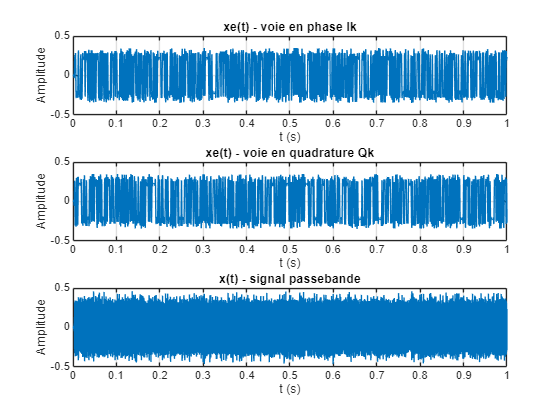


%% Plot signaux xe(t) et x(t)
figure;
subplot(3,1,1);
plot(t_test, real(xe_test));
title('xe(t) - voie en phase Ik'); xlabel('t (s)'); ylabel('Amplitude'); grid on;
xlim([0, 1])
subplot(3,1,2);
plot(t_test, imag(xe_test));
title('xe(t) - voie en quadrature Qk'); xlabel('t (s)'); ylabel('Amplitude'); grid on;
xlim([0, 1])
subplot(3,1,3);
plot(t_test, x_test);
title('x(t) - signal passebande'); xlabel('t (s)'); ylabel('Amplitude'); grid on;
xlim([0, 1]);

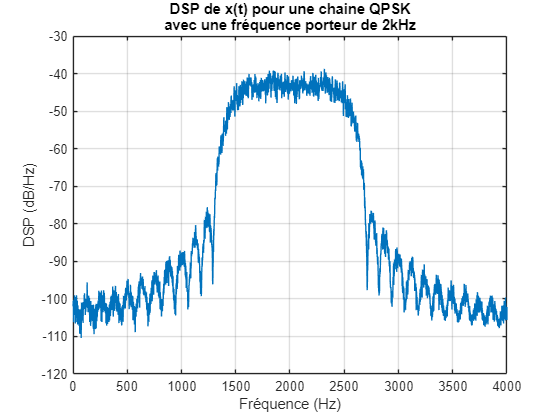

%% DSP de x(t)
figure;
[pxx, f] = pwelch(x_test, [], [], [], Fs);
plot(f, 10*log10(pxx));
title({'DSP de x(t) pour une chaine QPSK', 'avec une fréquence porteur de 2kHz'}); xlabel('Fréquence (Hz)'); ylabel('DSP (dB/Hz)'); grid on;
xlim([0, 4000]);

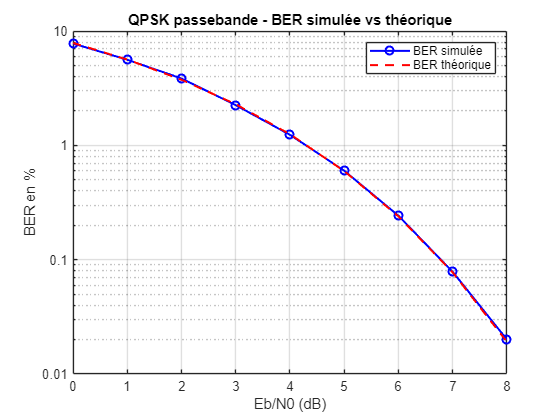


%% Tracé BER
figure;
semilogy(tab_EbN0_dB, BER_simu*100, 'bo-', 'LineWidth', 1.5, 'MarkerSize', 6); hold on;
semilogy(tab_EbN0_dB, BER_theo*100, 'r--', 'LineWidth', 1.5);
legend('BER simulée', 'BER théorique');
xlabel('Eb/N0 (dB)'); ylabel('BER en %');
title('QPSK passebande - BER simulée vs théorique');
ytickformat('%.1f')
ax = gca;
ax.YTickLabel = string(ax.YTick);
grid on;

#### En basse fréquence

BER_simu= zeros(1, length(tab_EbN0_dB));
BER_theo= zeros(1, length(tab_EbN0_dB));

for k = 1:length(tab_EbN0_dB)
    EbN0_dB  = tab_EbN0_dB(k);
    EbN0_lin = 10^(EbN0_dB/10);

    nb_erreurs=0;
    compteur=0;

    while nb_erreurs<1000

        %% Génération des bits
        bits = randi([0,1], 1, nb_bits_block);

        %% Mapping : bits -> symboles complexes dk = Ik + j*Qk 
        % (voir schéma figure 1 les notations sont les mêmes)
        bits_reshape = reshape(bits, log2(M), []).';
        Ik=2*bits_reshape(:,1)-1;
        Qk=2*bits_reshape(:,2)-1;
        dk=(Ik+1j*Qk)/sqrt(2);
        
        % Stockage des bits pour comparaison futur
        symbole_binaire=bits_reshape;

        %% Oversampling:sum dk*delta(t - kTs)
        diracs=kron(dk.',[1 zeros(1, Ns-1)]);

        %% Pulse Shaping: xe(t)=sum dk*h(t-kTs)
        xe=filter(h,1,diracs);
        xe=xe(:).';
        Pxe=mean(abs(xe).^2);

        %% Canal AWGN : r(t) = x(t) + n(t)
        sigma_n=(Pxe*Ns)/(2*log2(M)*EbN0_lin);
        n_I= sqrt(sigma_n)*randn(1, length(xe));
        n_Q= sqrt(sigma_n)*randn(1, length(xe));
        r=xe+(n_I+1j*n_Q);

        %% Reception filtering : filtre adapté p(t)
        r_filtre= filter(h, 1, r);

        %% Sampling : échantillonnage à t0 + m*Ns
        r_echantillonne=r_filtre(t0:Ns:end);
        nb_symb= min(length(r_echantillonne), length(dk));
        % t0 fait perdre des valeurs 
        % donc il faut recalibré
        r_echantillonne= r_echantillonne(1:nb_symb);

        %% Decision
        dk_decide=zeros(nb_symb, 2);
        dk_decide(real(r_echantillonne)>0, 1)= 1;
        dk_decide(imag(r_echantillonne)>0, 2)= 1;

        %% Demapping : symboles décidés -> bits
        nb_erreurs=nb_erreurs+sum(sum(symbole_binaire(1:nb_symb,:) ~= dk_decide));
        compteur=compteur+1;

    end

    BER_simu(k)=nb_erreurs/(compteur*nb_bits_block);
    BER_theo(k)=erfc(sqrt(EbN0_lin))/2;

    fprintf('Eb/N0 = %d dB -> BER = %.2e (nb blocs = %d)\n', EbN0_dB, BER_simu(k), compteur);
end

Eb/N0 = 0 dB -> BER = 8.18e-02 (nb blocs = 3)
Eb/N0 = 1 dB -> BER = 5.60e-02 (nb blocs = 4)
Eb/N0 = 2 dB -> BER = 3.61e-02 (nb blocs = 5)
Eb/N0 = 3 dB -> BER = 2.26e-02 (nb blocs = 8)
Eb/N0 = 4 dB -> BER = 1.23e-02 (nb blocs = 14)
Eb/N0 = 5 dB -> BER = 5.98e-03 (nb blocs = 28)
Eb/N0 = 6 dB -> BER = 2.47e-03 (nb blocs = 68)
Eb/N0 = 7 dB -> BER = 7.51e-04 (nb blocs = 222)
Eb/N0 = 8 dB -> BER = 1.97e-04 (nb blocs = 848)


%% On refait mais sans le bruit
bits_reshape = reshape(bits, log2(M), []).';
Ik=2*bits_reshape(:,1)-1;
Qk=2*bits_reshape(:,2)-1;
dk_test=(Ik+j*Qk)/sqrt(2);
symbole_binaire_test=zeros(length(dk_test), 2);
symbole_binaire_test(real(dk_test)>0, 1)= 1;
symbole_binaire_test(imag(dk_test)>0, 2)= 1;


diracs_test = kron(dk_test.', [1 zeros(1, Ns-1)]);
xe_test = filter(h, 1, diracs_test);
xe_test= xe_test(:).';
x_test = xe_test;

r_filt_test= filter(h, 1, x_test);
r_ech_test= r_filt_test(t0:Ns:end);
nb_symb_test= min(length(r_ech_test), length(dk_test));
r_ech_test= r_ech_test(1:nb_symb_test);

dk_decide_test = zeros(nb_symb_test, 2);
dk_decide_test(real(r_ech_test)> 0, 1)= 1;
dk_decide_test(imag(r_ech_test)> 0, 2)= 1;

BER_no_noise = sum(sum(symbole_binaire_test(1:nb_symb_test,:) ~= dk_decide_test)) / (nb_symb_test*2);
% le *2 est nécessaire pour avoir le nombre de bits
fprintf('BER sans bruit = %e (doit être 0)\n', BER_no_noise);

BER sans bruit = 0.000000e+00 (doit être 0)


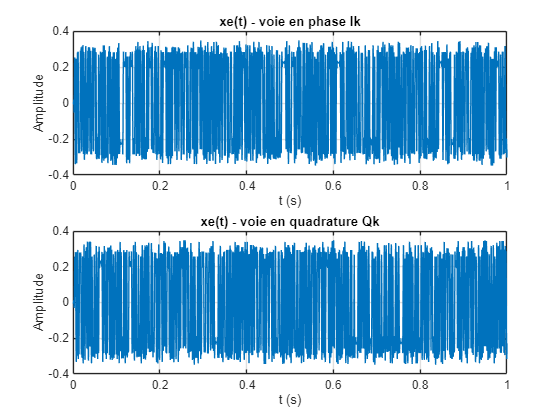

%% Plot signaux xe(t) et x(t)
figure;
subplot(2,1,1);
plot(t_test, real(xe_test));
title('xe(t) - voie en phase Ik'); xlabel('t (s)'); ylabel('Amplitude'); grid on;
xlim([0, 1])

subplot(2,1,2);
plot(t_test, imag(xe_test));
title('xe(t) - voie en quadrature Qk'); xlabel('t (s)'); ylabel('Amplitude'); grid on;
xlim([0, 1]);

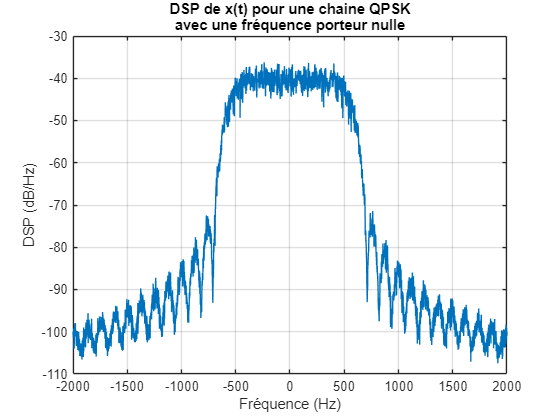


%% DSP de x(t)
figure;
[pxx, f] = pwelch(x_test, [], [], [], Fs, 'centered');
plot(f, 10*log10(pxx));
title({'DSP de x(t) pour une chaine QPSK', 'avec une fréquence porteur nulle'}); xlabel('Fréquence (Hz)'); ylabel('DSP (dB/Hz)'); grid on;
xlim([-2000, 2000]);

## IMPORTANT! LA DSP EST DESORMAIS CENTRE EN 0!

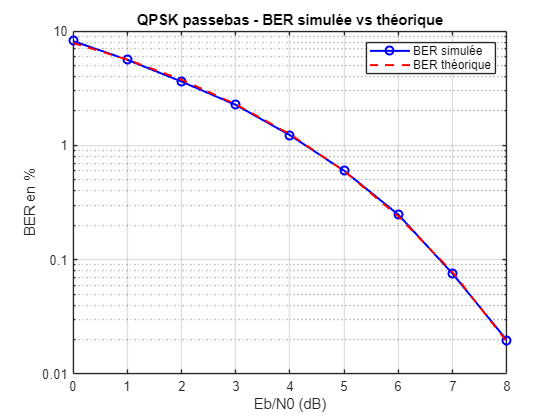

%% Tracé BER
figure;
semilogy(tab_EbN0_dB, BER_simu*100, 'bo-', 'LineWidth', 1.5, 'MarkerSize', 6); hold on;
semilogy(tab_EbN0_dB, BER_theo*100, 'r--', 'LineWidth', 1.5);
legend('BER simulée', 'BER théorique');
xlabel('Eb/N0 (dB)'); ylabel('BER en %');
title('QPSK passebas - BER simulée vs théorique');
ytickformat('%.1f')
ax = gca;
ax.YTickLabel = string(ax.YTick);
grid on;

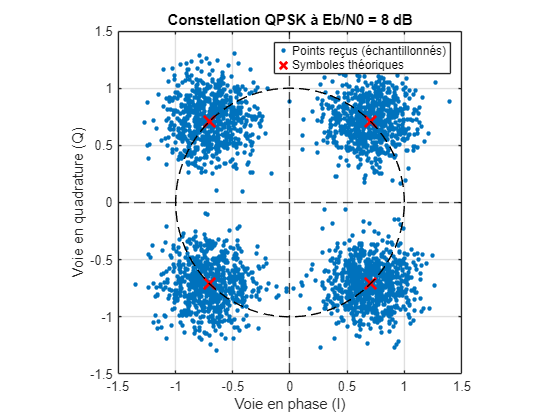

% Affichage de la constellation
% On choisit par exemple le dernier Eb/N0 simulé (8 dB)
figure;
plot(r_echantillonne, '.', 'MarkerSize', 10); % Affiche les points reçus
hold on;
grid on;
plot(dk, 'rx', 'LineWidth', 2, 'MarkerSize', 12); % Affiche les symboles théoriques
title(['Constellation QPSK à Eb/N0 = ' num2str(EbN0_dB) ' dB']);
xlabel('Voie en phase (I)');
ylabel('Voie en quadrature (Q)');
legend('Points reçus (échantillonnés)', 'Symboles théoriques');
% 2. Tracer le cercle unitaire pour se repérer visuellement
theta = linspace(0, 2*pi, 100);
plot(cos(theta), sin(theta), 'k--', 'HandleVisibility', 'off');
xline(0, 'k--', 'HandleVisibility', 'off');
yline(0, 'k--', 'HandleVisibility', 'off');
axis([-1.5 1.5 -1.5 1.5]); 
xticks(-1.5:0.5:1.5); 
yticks(-1.5:0.5:1.5);
axis square; % Pour avoir un repère orthonormé

## **Chaine 4-ASK**

#### **En bande passante**

%% Paramètres
Fs= 12000;
Rb= 6000;
Fc= 2000;
alpha= 0.35;
M= 4;
Rs = Rb/log2(M); %débit de symbole
Ns= Fs/Rs;
span= 8;
nb_bits_block= 6000;%plus on mets un chiffre grand mieux le grap final suivera 
% le théorique par contre moins le graph des xe sera lisible au premier abord 
N= span*Ns +1; %TP1 modulateur 4

%% Filtre RRC p(t)
h= rcosdesign(alpha, span, Ns, 'sqrt');
t0= N;

%% Boucle BER
tab_EbN0_dB = [0:8];
BER_simu= zeros(1, length(tab_EbN0_dB));
BER_theo= zeros(1, length(tab_EbN0_dB));

for k = 1:length(tab_EbN0_dB)
    EbN0_dB  = tab_EbN0_dB(k);
    EbN0_lin = 10^(EbN0_dB/10);

    nb_erreurs=0;
    compteur=0;

    while nb_erreurs<5000

        %% Génération des bits
        bits = randi([0,1], 1, nb_bits_block);

        %% Mapping : bits -> symboles complexes dk = Ik + j*Qk 
        % (voir schéma figure 1 les notations sont les mêmes)
        bits_reshape = reshape(bits, log2(M), []).';
        val_dec = bi2de(bits_reshape, 'left-msb');
        mapping_table = [-3, -1, 3, 1];
        dk = mapping_table(val_dec + 1).';
        
        % Stockage des bits pour comparaison futur
        symbole_binaire=bits_reshape;

        %% Oversampling:sum dk*delta(t - kTs)
        diracs=kron(dk.',[1 zeros(1, Ns-1)]);

        %% Pulse Shaping: xe(t)=sum dk*h(t-kTs)
        xe=filter(h,1,diracs);
        xe=xe(:).';

        %% Frequency translation : x(t) = Re[xe(t) * exp(j2pi*fc*t)]
        t_vect=(0:length(xe)-1)/Fs;
        x=real(xe.*exp(j*2*pi*Fc*t_vect));
        Px=mean(abs(x).^2);

        %% Canal AWGN : r(t) = x(t) + n(t)
        sigma_n=(Px*Ns)/(2*log2(M)*EbN0_lin);
        n= sqrt(sigma_n)*randn(1, length(x));
        r=x+n;

        %% Baseband translation :
        %  I : r(t)*cos(2pi*fc*t)
        %  Q : r(t)*(-j)*sin(2pi*fc*t)
        %  -> r(t)*exp(-j2pi*fc*t)
        r_bb =r.*exp(-j*2*pi*Fc*t_vect); % = 1/2*x_e
        r_bb = 2*r_bb; %On multiplie par 2 pour compenser
        %% Reception filtering : filtre adapté p(t)
        r_filtre= filter(h, 1, r_bb);

        %% Sampling : échantillonnage à t0 + m*Ns
        r_echantillonne=r_filtre(t0:Ns:end);
        nb_symb= min(length(r_echantillonne), length(dk));
        % t0 fait perdre des valeurs 
        % donc il faut recalibré
        r_echantillonne= r_echantillonne(1:nb_symb);
        r_real = real(r_echantillonne).';

        %% Decision
        dk_decide=zeros(nb_symb, 2);
        dk_decide(r_real > 0, 1) = 1;
        dk_decide(r_real > -2 & r_real < 2, 2) = 1;

        %% Demapping : symboles décidés -> bits
        nb_erreurs=nb_erreurs+sum(sum(symbole_binaire(1:nb_symb,:) ~= dk_decide));
        compteur=compteur+1;

    end

    BER_simu(k)=nb_erreurs/(compteur*nb_bits_block);
    BER_theo(k)=3/8*erfc(sqrt(2/5*EbN0_lin));

    fprintf('Eb/N0 = %d dB -> BER = %.2e (nb blocs = %d)\n', EbN0_dB, BER_simu(k), compteur);
end

Eb/N0 = 0 dB -> BER = 1.38e-01 (nb blocs = 7)
Eb/N0 = 1 dB -> BER = 1.23e-01 (nb blocs = 7)
Eb/N0 = 2 dB -> BER = 9.66e-02 (nb blocs = 9)
Eb/N0 = 3 dB -> BER = 7.70e-02 (nb blocs = 11)
Eb/N0 = 4 dB -> BER = 5.92e-02 (nb blocs = 15)
Eb/N0 = 5 dB -> BER = 4.20e-02 (nb blocs = 20)
Eb/N0 = 6 dB -> BER = 2.76e-02 (nb blocs = 31)
Eb/N0 = 7 dB -> BER = 1.71e-02 (nb blocs = 49)
Eb/N0 = 8 dB -> BER = 9.55e-03 (nb blocs = 88)


%% On refait mais sans le bruit
bits_reshape = reshape(bits, log2(M), []).';
val_dec = bi2de(bits_reshape, 'left-msb');
mapping_table = [-3, -1, 3, 1];
dk_test=mapping_table(val_dec + 1).';
symbole_binaire_test=bits_reshape;

diracs_test = kron(dk_test.', [1 zeros(1, Ns-1)]);
xe_test = filter(h, 1, diracs_test);
xe_test= xe_test(:).';
t_test= (0:length(xe_test)-1) / Fs;
x_test = real(xe_test.* exp(j*2*pi*Fc*t_test));

r_bb_test= x_test.*exp(-j*2*pi*Fc*t_test);
r_bb_test=2*r_bb_test;
r_filt_test= filter(h, 1, r_bb_test);
% Avant l'échantillonnage, on normalise par la réponse impulsionnelle combinée
r_ech_test= r_filt_test(t0:Ns:end);
nb_symb_test= min(length(r_ech_test), length(dk_test));
r_ech_test= r_ech_test(1:nb_symb_test);
r_real_test = real(r_ech_test);

dk_decide_test = zeros(nb_symb_test, 2);
dk_decide_test(r_real_test > 0, 1) = 1;
dk_decide_test(r_real_test > -2 & r_real_test < 2, 2) = 1;

BER_no_noise = sum(sum(symbole_binaire_test(1:nb_symb_test,:) ~= dk_decide_test)) / (nb_symb_test*2);
% le *2 est nécessaire pour avoir le nombre de bits
fprintf('BER sans bruit = %e (doit être 0)\n', BER_no_noise);

BER sans bruit = 0.000000e+00 (doit être 0)


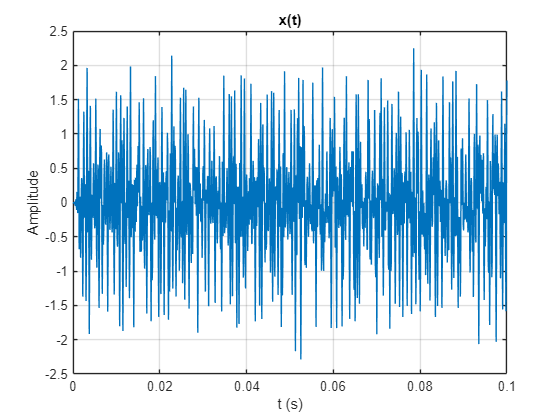

%% Plot signaux xe(t) et x(t)
figure;
plot(t_test, real(x_test));
title('x(t)'); xlabel('t (s)'); ylabel('Amplitude'); grid on; xlim([0, 0.1]);

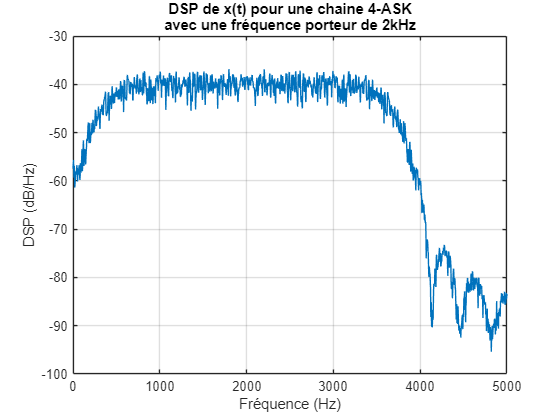


%% DSP de x(t)
figure;
[pxx, f] = pwelch(x_test, [], [], [], Fs, "centered");
plot(f, 10*log10(pxx));
title({'DSP de x(t) pour une chaine 4-ASK', 'avec une fréquence porteur de 2kHz'}); xlabel('Fréquence (Hz)'); ylabel('DSP (dB/Hz)'); grid on;
xlim([0, 5000]);

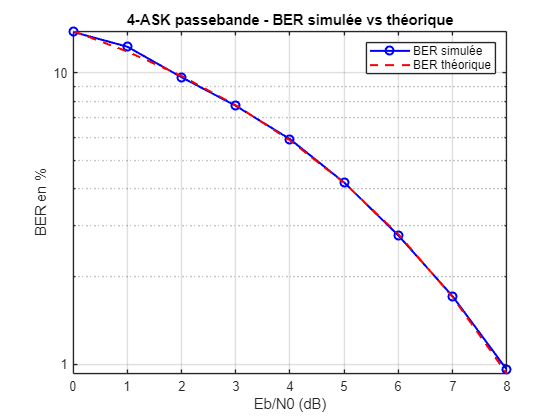

%% Tracé BER
figure;
semilogy(tab_EbN0_dB, BER_simu*100, 'bo-', 'LineWidth', 1.5, 'MarkerSize', 6); hold on;
semilogy(tab_EbN0_dB, BER_theo*100, 'r--', 'LineWidth', 1.5);
legend('BER simulée', 'BER théorique');
xlabel('Eb/N0 (dB)'); ylabel('BER en %');
title('4-ASK passebande - BER simulée vs théorique');
ytickformat('%.1f')
ax = gca;
ax.YTickLabel = string(ax.YTick);
grid on;

#### En passe bas:

BER_simu= zeros(1, length(tab_EbN0_dB));
BER_theo= zeros(1, length(tab_EbN0_dB));

for k = 1:length(tab_EbN0_dB)
    EbN0_dB  = tab_EbN0_dB(k);
    EbN0_lin = 10^(EbN0_dB/10);

    nb_erreurs=0;
    compteur=0;

    while nb_erreurs<5000

        %% Génération des bits
        bits = randi([0,1], 1, nb_bits_block);

        %% Mapping : bits -> symboles complexes dk = Ik + j*Qk 
        % (voir schéma figure 1 les notations sont les mêmes)
        bits_reshape = reshape(bits, log2(M), []).';
        val_dec = bi2de(bits_reshape, 'left-msb');
        mapping_table = [-3, -1, 3, 1];
        dk = mapping_table(val_dec + 1).';
        
        % Stockage des bits pour comparaison futur
        symbole_binaire=bits_reshape;

        %% Oversampling:sum dk*delta(t - kTs)
        diracs=kron(dk.',[1 zeros(1, Ns-1)]);

        %% Pulse Shaping: xe(t)=sum dk*h(t-kTs)
        xe=filter(h,1,diracs);
        xe=xe(:).';

        %% Frequency translation : x(t) = Re[xe(t) * exp(j2pi*fc*t)]
        t_vect=(0:length(xe)-1)/Fs;
        Pxe=mean(abs(xe).^2);

        %% Canal AWGN : r(t) = x(t) + n(t)
        sigma_n=(Pxe*Ns)/(2*log2(M)*EbN0_lin);
        n_I= sqrt(sigma_n)*randn(1, length(xe));
        n_Q= sqrt(sigma_n)*randn(1, length(xe));
        r=xe+(n_I+1j*n_Q);
        
        %% Reception filtering : filtre adapté p(t)
        r_filtre= filter(h, 1, r);

        %% Sampling : échantillonnage à t0 + m*Ns
        r_echantillonne=r_filtre(t0:Ns:end);
        nb_symb= min(length(r_echantillonne), length(dk));
        % t0 fait perdre des valeurs 
        % donc il faut recalibré
        r_echantillonne= r_echantillonne(1:nb_symb);
        r_real = real(r_echantillonne).';

        %% Decision
        dk_decide=zeros(nb_symb, 2);
        dk_decide(r_real > 0, 1) = 1;
        dk_decide(r_real > -2 & r_real < 2, 2) = 1;

        %% Demapping : symboles décidés -> bits
        nb_erreurs=nb_erreurs+sum(sum(symbole_binaire(1:nb_symb,:) ~= dk_decide));
        compteur=compteur+1;

    end

    BER_simu(k)=nb_erreurs/(compteur*nb_bits_block);
    BER_theo(k)=3/8*erfc(sqrt(2/5*EbN0_lin));

    fprintf('Eb/N0 = %d dB -> BER = %.2e (nb blocs = %d)\n', EbN0_dB, BER_simu(k), compteur);
end

Eb/N0 = 0 dB -> BER = 1.43e-01 (nb blocs = 2)
Eb/N0 = 1 dB -> BER = 1.17e-01 (nb blocs = 2)
Eb/N0 = 2 dB -> BER = 9.37e-02 (nb blocs = 2)
Eb/N0 = 3 dB -> BER = 8.28e-02 (nb blocs = 3)
Eb/N0 = 4 dB -> BER = 5.83e-02 (nb blocs = 3)
Eb/N0 = 5 dB -> BER = 4.21e-02 (nb blocs = 4)
Eb/N0 = 6 dB -> BER = 2.82e-02 (nb blocs = 6)
Eb/N0 = 7 dB -> BER = 1.76e-02 (nb blocs = 10)
Eb/N0 = 8 dB -> BER = 9.04e-03 (nb blocs = 19)


%% On refait mais sans le bruit
bits_reshape = reshape(bits, log2(M), []).';
val_dec = bi2de(bits_reshape, 'left-msb');
mapping_table = [-3, -1, 3, 1];
dk_test=mapping_table(val_dec + 1).';
symbole_binaire_test=bits_reshape;

diracs_test = kron(dk_test.', [1 zeros(1, Ns-1)]);
xe_test = filter(h, 1, diracs_test);
xe_test= xe_test(:).';
t_test= (0:length(xe_test)-1) / Fs;
x_test = xe_test;

r_filt_test= filter(h, 1, x_test);
% Avant l'échantillonnage, on normalise par la réponse impulsionnelle combinée
r_ech_test= r_filt_test(t0:Ns:end);
nb_symb_test= min(length(r_ech_test), length(dk_test));
r_ech_test= r_ech_test(1:nb_symb_test);
r_real_test = real(r_ech_test);

dk_decide_test = zeros(nb_symb_test, 2);
dk_decide_test(r_real_test > 0, 1) = 1;
dk_decide_test(r_real_test > -2 & r_real_test < 2, 2) = 1;

BER_no_noise = sum(sum(symbole_binaire_test(1:nb_symb_test,:) ~= dk_decide_test)) / (nb_symb_test*2);
% le *2 est nécessaire pour avoir le nombre de bits
fprintf('BER sans bruit = %e (doit être 0)\n', BER_no_noise);

BER sans bruit = 0.000000e+00 (doit être 0)


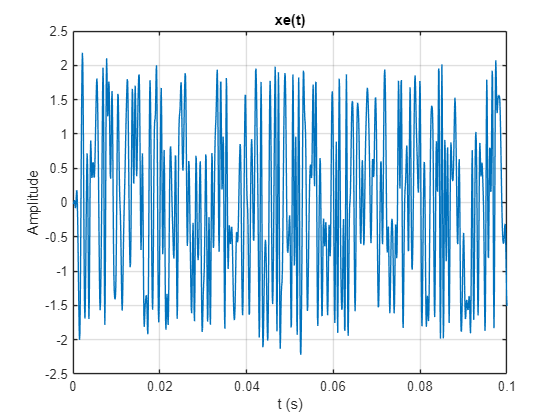

%% Plot signaux xe(t) et x(t)
figure;
plot(t_test, real(x_test));
title('xe(t)'); xlabel('t (s)'); ylabel('Amplitude'); grid on; xlim([0, 0.1]);

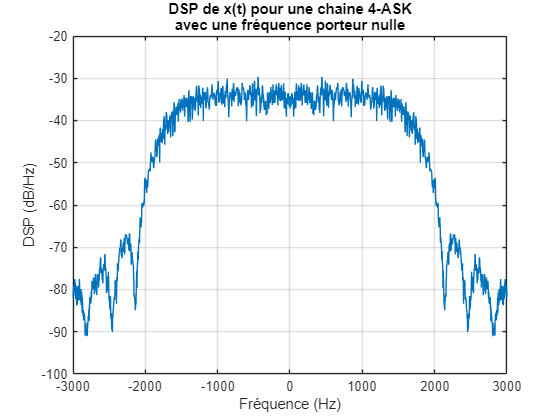

%% DSP de x(t)
figure;
[pxx, f] = pwelch(x_test, [], [], [], Fs, "centered");
plot(f, 10*log10(pxx));
title({'DSP de x(t) pour une chaine 4-ASK', 'avec une fréquence porteur nulle'}); xlabel('Fréquence (Hz)'); ylabel('DSP (dB/Hz)'); grid on;
xlim([-3000, 3000]);

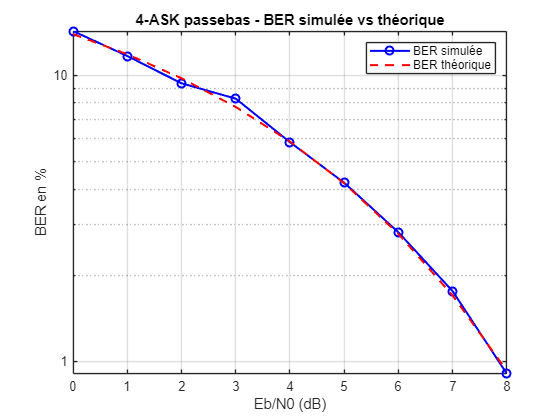

%% Tracé BER
figure;
semilogy(tab_EbN0_dB, BER_simu*100, 'bo-', 'LineWidth', 1.5, 'MarkerSize', 6); hold on;
semilogy(tab_EbN0_dB, BER_theo*100, 'r--', 'LineWidth', 1.5);
legend('BER simulée', 'BER théorique');
xlabel('Eb/N0 (dB)'); ylabel('BER en %');
title('4-ASK passebas - BER simulée vs théorique');
ytickformat('%.1f')
ax = gca;
ax.YTickLabel = string(ax.YTick);
grid on;

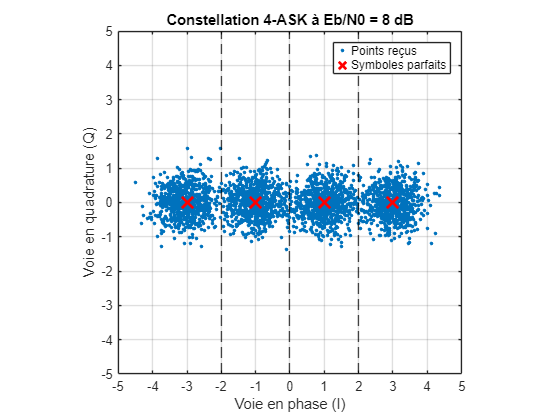

%% Affichage de la constellation 4-ASK
figure;
% On trace les points reçus (bruité)
plot(r_echantillonne, '.', 'MarkerSize', 8, 'DisplayName', 'Points reçus');
hold on;
grid on;

% On trace les 4 symboles théoriques par-dessus
symboles_theoriques = [-3, -1, 1, 3];
plot(symboles_theoriques, zeros(1,4), 'rx', 'MarkerSize', 12, 'LineWidth', 2, 'DisplayName', 'Symboles parfaits');

title(['Constellation 4-ASK à Eb/N0 = ' num2str(EbN0_dB) ' dB']);
xlabel('Voie en phase (I)');
ylabel('Voie en quadrature (Q)');
legend;
frontieres = [-2, 0, 2];
for f = frontieres
    % Lignes verticales (Frontières de la voie I)
    xline(f, 'k--', 'HandleVisibility', 'off');
end
% Important pour ne pas déformer la vue :
axis([-5 5 -5 5]); 
xticks(-5:1:5); 
yticks(-5:1:5);
axis square;

## Chaine 8-PSK

#### En bande passante

%% Paramètres
Fs= 12000;
Rb= 6000;
Fc= 2000;
alpha= 0.35;
M= 8;
Rs = Rb/log2(M); %débit de symbole
Ns= Fs/Rs;
span= 8;
nb_bits_block= 6000;%plus on mets un chiffre grand mieux le grap final suivera 
% le théorique par contre moins le graph des xe sera lisible au premier abord 
N= span*Ns +1; %TP1 modulateur 4

%% Filtre RRC p(t)
h= rcosdesign(alpha, span, Ns, 'sqrt');
t0= N;

%% Boucle BER
tab_EbN0_dB = [0:8];
BER_simu= zeros(1, length(tab_EbN0_dB));
BER_theo= zeros(1, length(tab_EbN0_dB));

for k = 1:length(tab_EbN0_dB)
    EbN0_dB  = tab_EbN0_dB(k);
    EbN0_lin = 10^(EbN0_dB/10);

    nb_erreurs=0;
    compteur=0;

    while nb_erreurs<5000

        %% Génération des bits
        bits = randi([0,1], 1, nb_bits_block);

        %% Mapping 8-PSK avec Gray
        bits_reshape = reshape(bits, log2(M), []).'; % Paquets de 3 bits
        val_dec = bi2de(bits_reshape, 'left-msb');
        
        % Table de correspondance Gray -> Phases (en radians)
        % Pour les valeurs décimales de 0 à 7, on associe les angles :
        % 000(0)->0, 001(1)->pi/4, 011(3)->pi/2, 010(2)->3pi/4, etc.
        gray_phases = [0, pi/4, 3*pi/4, pi/2, 7*pi/4, 3*pi/2, pi, 5*pi/4];
        
        % On récupère la phase correspondante
        phases_symb = gray_phases(val_dec + 1);
        % On crée le symbole complexe sur le cercle unitaire
        dk = exp(1j * phases_symb).';
        
        % Stockage des bits pour comparaison futur
        symbole_binaire=bits_reshape;

        %% Oversampling:sum dk*delta(t - kTs)
        diracs=kron(dk.',[1 zeros(1, Ns-1)]);

        %% Pulse Shaping: xe(t)=sum dk*h(t-kTs)
        xe=filter(h,1,diracs);
        xe=xe(:).';

        %% Frequency translation : x(t) = Re[xe(t) * exp(j2pi*fc*t)]
        t_vect=(0:length(xe)-1)/Fs;
        x=real(xe.*exp(j*2*pi*Fc*t_vect));
        Px=mean(abs(x).^2);

        %% Canal AWGN : r(t) = x(t) + n(t)
        sigma_n=(Px*Ns)/(2*log2(M)*EbN0_lin);
        n= sqrt(sigma_n)*randn(1, length(x));
        r=x+n;

        %% Baseband translation :
        %  I : r(t)*cos(2pi*fc*t)
        %  Q : r(t)*(-j)*sin(2pi*fc*t)
        %  -> r(t)*exp(-j2pi*fc*t)
        r_bb =r.*exp(-j*2*pi*Fc*t_vect); % = 1/2*x_e

        %% Reception filtering : filtre adapté p(t)
        r_filtre= filter(h, 1, r_bb);

        %% Sampling : échantillonnage à t0 + m*Ns
        r_echantillonne=r_filtre(t0:Ns:end);
        nb_symb= min(length(r_echantillonne), length(dk));
        % t0 fait perdre des valeurs 
        % donc il faut recalibré
        r_echantillonne= r_echantillonne(1:nb_symb);
        phases_recues = angle(r_echantillonne);
        phases_recues(phases_recues < 0) = phases_recues(phases_recues < 0) + 2*pi;%pour avoir du [0;2pi] plutot que [-pi, pi]
        %% Decision
        dk_decide = zeros(length(phases_recues), 3); % Matrice de 3 bits

        for i = 1:length(phases_recues)
            % On calcule la distance angulaire avec les 8 phases théoriques
            [~, index_min] = min(abs(exp(1j*phases_recues(i)) - exp(1j*gray_phases)));
            
            % On fait le demapping (inverse de bi2de)
            valeur_decimale_decidee = index_min - 1; 
            dk_decide(i, :) = de2bi(valeur_decimale_decidee, 3, 'left-msb');
        end

        %% Demapping : symboles décidés -> bits
        nb_erreurs=nb_erreurs+sum(sum(symbole_binaire(1:nb_symb,:) ~= dk_decide));
        compteur=compteur+1;

    end

    BER_simu(k)=nb_erreurs/(compteur*nb_bits_block);
    BER_theo(k) = (2/log2(M)) *(1/2)* erfc(sqrt(EbN0_lin*log2(M))*sin(pi/M));

    fprintf('Eb/N0 = %d dB -> BER = %.2e (nb blocs = %d)\n', EbN0_dB, BER_simu(k), compteur);
end

Eb/N0 = 0 dB -> BER = 1.21e-01 (nb blocs = 7)
Eb/N0 = 1 dB -> BER = 9.89e-02 (nb blocs = 9)
Eb/N0 = 2 dB -> BER = 8.13e-02 (nb blocs = 11)
Eb/N0 = 3 dB -> BER = 6.29e-02 (nb blocs = 14)
Eb/N0 = 4 dB -> BER = 4.60e-02 (nb blocs = 19)
Eb/N0 = 5 dB -> BER = 3.16e-02 (nb blocs = 27)
Eb/N0 = 6 dB -> BER = 2.02e-02 (nb blocs = 42)
Eb/N0 = 7 dB -> BER = 1.22e-02 (nb blocs = 69)
Eb/N0 = 8 dB -> BER = 6.31e-03 (nb blocs = 133)


%% On refait mais sans le bruit
%% Mapping 8-PSK avec Gray
bits_reshape = reshape(bits, log2(M), []).'; % Paquets de 3 bits
val_dec = bi2de(bits_reshape, 'left-msb');

% Table de correspondance Gray -> Phases (en radians)
% Pour les valeurs décimales de 0 à 7, on associe les angles :
% 000(0)->0, 001(1)->pi/4, 011(3)->pi/2, 010(2)->3pi/4, etc.
gray_phases = [0, pi/4, 3*pi/4, pi/2, 7*pi/4, 3*pi/2, pi, 5*pi/4];

% On récupère la phase correspondante
phases_symb = gray_phases(val_dec + 1);

% On crée le symbole complexe sur le cercle unitaire
dk_test = exp(1j * phases_symb).';
symbole_binaire_test = bits_reshape;


diracs_test = kron(dk_test.', [1 zeros(1, Ns-1)]);
xe_test = filter(h, 1, diracs_test);
xe_test= xe_test(:).';
t_test= (0:length(xe_test)-1) / Fs;
x_test=real(xe_test.* exp(j*2*pi*Fc*t_test));

r_bb_test= x_test.*exp(-j*2*pi*Fc*t_test);
r_filt_test= filter(h, 1, r_bb_test);
r_ech_test= r_filt_test(t0:Ns:end);
nb_symb_test= min(length(r_ech_test), length(dk_test));
r_ech_test= r_ech_test(1:nb_symb_test);

%% Décision 8-PSK
% On récupère la phase du signal reçu
phases_recues_test = angle(r_ech_test);

% On ramène les angles négatifs entre 0 et 2*pi pour simplifier
phases_recues_test(phases_recues_test < 0) = phases_recues_test(phases_recues_test < 0) + 2*pi;

% On trouve l'angle théorique le plus proche
% (Les frontières de décision sont tous les 22.5° soit pi/8)
dk_decide_test = zeros(length(phases_recues_test), 3); % Matrice de 3 bits

for i = 1:length(phases_recues_test)
    % On calcule la distance angulaire avec les 8 phases théoriques
    [~, index_min] = min(abs(exp(1j*phases_recues_test(i)) - exp(1j*gray_phases)));
    
    % On fait le demapping (inverse de bi2de)
    valeur_decimale_decidee_test = index_min - 1; 
    dk_decide_test(i, :) = de2bi(valeur_decimale_decidee_test, 3, 'left-msb');
end

BER_no_noise = sum(sum(symbole_binaire_test(1:nb_symb_test,:) ~= dk_decide_test)) / (nb_symb_test*2);
% le *2 est nécessaire pour avoir le nombre de bits
fprintf('BER sans bruit = %e (doit être 0)\n', BER_no_noise);%% Plot signaux xe(t) et x(t)

BER sans bruit = 0.000000e+00 (doit être 0)


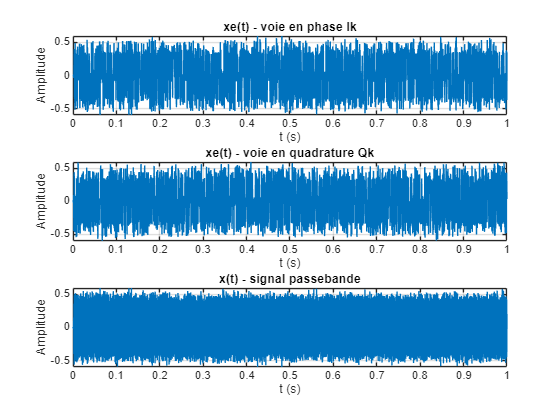

figure;
subplot(3,1,1);
plot(t_test, real(xe_test));
title('xe(t) - voie en phase Ik'); xlabel('t (s)'); ylabel('Amplitude'); grid on;xlim([0, 1]);

subplot(3,1,2);
plot(t_test, imag(xe_test));
title('xe(t) - voie en quadrature Qk'); xlabel('t (s)'); ylabel('Amplitude'); grid on;xlim([0, 1]);

subplot(3,1,3);
plot(t_test, x_test);
title('x(t) - signal passebande'); xlabel('t (s)'); ylabel('Amplitude'); grid on;xlim([0, 1]);

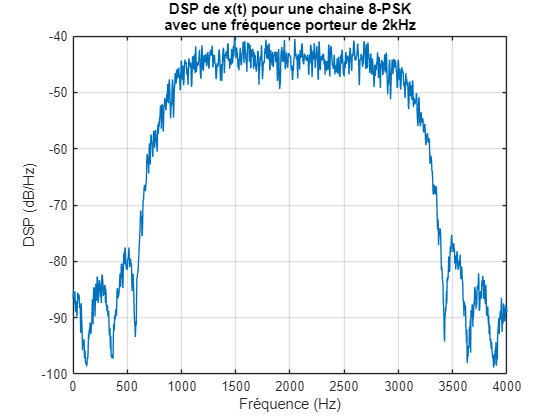

%% DSP de x(t)
figure;
[pxx, f] = pwelch(x_test, [], [], [], Fs);
plot(f, 10*log10(pxx));
title({'DSP de x(t) pour une chaine 8-PSK', 'avec une fréquence porteur de 2kHz'}); xlabel('Fréquence (Hz)'); ylabel('DSP (dB/Hz)'); grid on;
xlim([0, 4000]);

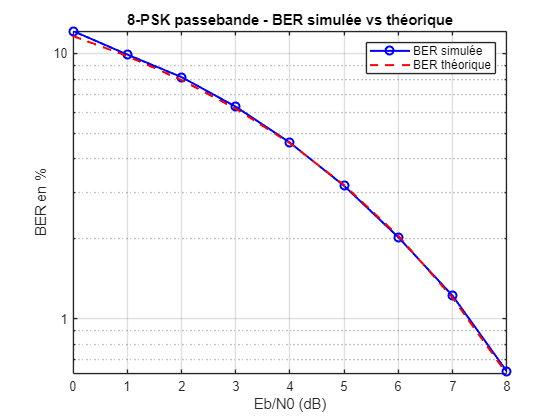

%% Tracé BER
figure;
semilogy(tab_EbN0_dB, BER_simu*100, 'bo-', 'LineWidth', 1.5, 'MarkerSize', 6); hold on;
semilogy(tab_EbN0_dB, BER_theo*100, 'r--', 'LineWidth', 1.5);
legend('BER simulée', 'BER théorique');
xlabel('Eb/N0 (dB)'); ylabel('BER en %');
title('8-PSK passebande - BER simulée vs théorique');
ytickformat('%.1f')
ax = gca;
ax.YTickLabel = string(ax.YTick);
grid on;

#### En passe bas:

BER_simu= zeros(1, length(tab_EbN0_dB));
BER_theo= zeros(1, length(tab_EbN0_dB));

for k = 1:length(tab_EbN0_dB)
    EbN0_dB  = tab_EbN0_dB(k);
    EbN0_lin = 10^(EbN0_dB/10);

    nb_erreurs=0;
    compteur=0;

    while nb_erreurs<5000

        %% Génération des bits
        bits = randi([0,1], 1, nb_bits_block);

        %% Mapping 8-PSK avec Gray
        bits_reshape = reshape(bits, log2(M), []).'; % Paquets de 3 bits
        val_dec = bi2de(bits_reshape, 'left-msb');
        
        % Table de correspondance Gray -> Phases (en radians)
        % Pour les valeurs décimales de 0 à 7, on associe les angles :
        % 000(0)->0, 001(1)->pi/4, 011(3)->pi/2, 010(2)->3pi/4, etc.
        gray_phases = [0, pi/4, 3*pi/4, pi/2, 7*pi/4, 3*pi/2, pi, 5*pi/4];
        
        % On récupère la phase correspondante
        phases_symb = gray_phases(val_dec + 1);
        % On crée le symbole complexe sur le cercle unitaire
        dk = exp(1j * phases_symb).';
        
        % Stockage des bits pour comparaison futur
        symbole_binaire=bits_reshape;

        %% Oversampling:sum dk*delta(t - kTs)
        diracs=kron(dk.',[1 zeros(1, Ns-1)]);

        %% Pulse Shaping: xe(t)=sum dk*h(t-kTs)
        xe=filter(h,1,diracs);
        xe=xe(:).';

        %% Frequency translation : x(t) = Re[xe(t) * exp(j2pi*fc*t)]
        t_vect=(0:length(xe)-1)/Fs;
        Pxe=mean(abs(xe).^2);

        %% Canal AWGN : r(t) = x(t) + n(t)
        sigma_n=(Pxe*Ns)/(2*log2(M)*EbN0_lin);
        n_I= sqrt(sigma_n)*randn(1, length(xe));
        n_Q= sqrt(sigma_n)*randn(1, length(xe));
        r=xe+(n_I+1j*n_Q);
        
        %% Reception filtering : filtre adapté p(t)
        r_filtre= filter(h, 1, r);

        %% Sampling : échantillonnage à t0 + m*Ns
        r_echantillonne=r_filtre(t0:Ns:end);
        nb_symb= min(length(r_echantillonne), length(dk));
        % t0 fait perdre des valeurs 
        % donc il faut recalibré
        r_echantillonne= r_echantillonne(1:nb_symb);
        phases_recues = angle(r_echantillonne);
        phases_recues(phases_recues < 0) = phases_recues(phases_recues < 0) + 2*pi;%pour avoir du [0;2pi] plutot que [-pi, pi]
        %% Decision
        dk_decide = zeros(length(phases_recues), 3); % Matrice de 3 bits

        for i = 1:length(phases_recues)
            % On calcule la distance angulaire avec les 8 phases théoriques
            [~, index_min] = min(abs(exp(1j*phases_recues(i)) - exp(1j*gray_phases)));
            
            % On fait le demapping (inverse de bi2de)
            valeur_decimale_decidee = index_min - 1; 
            dk_decide(i, :) = de2bi(valeur_decimale_decidee, 3, 'left-msb');
        end

        %% Demapping : symboles décidés -> bits
        nb_erreurs=nb_erreurs+sum(sum(symbole_binaire(1:nb_symb,:) ~= dk_decide));
        compteur=compteur+1;

    end

    BER_simu(k)=nb_erreurs/(compteur*nb_bits_block);
    BER_theo(k) = (2/log2(M)) *(1/2)* erfc(sqrt(EbN0_lin*log2(M))*sin(pi/M));

    fprintf('Eb/N0 = %d dB -> BER = %.2e (nb blocs = %d)\n', EbN0_dB, BER_simu(k), compteur);
end

Eb/N0 = 0 dB -> BER = 1.23e-01 (nb blocs = 7)
Eb/N0 = 1 dB -> BER = 1.01e-01 (nb blocs = 9)
Eb/N0 = 2 dB -> BER = 8.10e-02 (nb blocs = 11)
Eb/N0 = 3 dB -> BER = 6.31e-02 (nb blocs = 14)
Eb/N0 = 4 dB -> BER = 4.61e-02 (nb blocs = 19)
Eb/N0 = 5 dB -> BER = 3.13e-02 (nb blocs = 27)
Eb/N0 = 6 dB -> BER = 2.05e-02 (nb blocs = 41)
Eb/N0 = 7 dB -> BER = 1.21e-02 (nb blocs = 69)
Eb/N0 = 8 dB -> BER = 6.25e-03 (nb blocs = 134)


%% On refait mais sans le bruit
%% Mapping 8-PSK avec Gray
bits_reshape = reshape(bits, log2(M), []).'; % Paquets de 3 bits
val_dec = bi2de(bits_reshape, 'left-msb');

% Table de correspondance Gray -> Phases (en radians)
% Pour les valeurs décimales de 0 à 7, on associe les angles :
% 000(0)->0, 001(1)->pi/4, 011(3)->pi/2, 010(2)->3pi/4, etc.
gray_phases = [0, pi/4, 3*pi/4, pi/2, 7*pi/4, 3*pi/2, pi, 5*pi/4];

% On récupère la phase correspondante
phases_symb = gray_phases(val_dec + 1);

% On crée le symbole complexe sur le cercle unitaire
dk_test = exp(1j * phases_symb).';
symbole_binaire_test = bits_reshape;


diracs_test = kron(dk_test.', [1 zeros(1, Ns-1)]);
xe_test = filter(h, 1, diracs_test);
xe_test= xe_test(:).';
t_test= (0:length(xe_test)-1) / Fs;
x_test = xe_test;

r_filt_test= filter(h, 1, x_test);
r_ech_test= r_filt_test(t0:Ns:end);
nb_symb_test= min(length(r_ech_test), length(dk_test));
r_ech_test= r_ech_test(1:nb_symb_test);

%% Décision 8-PSK
% On récupère la phase du signal reçu
phases_recues_test = angle(r_ech_test);

% On ramène les angles négatifs entre 0 et 2*pi pour simplifier
phases_recues_test(phases_recues_test < 0) = phases_recues_test(phases_recues_test < 0) + 2*pi;

% On trouve l'angle théorique le plus proche
% (Les frontières de décision sont tous les 22.5° soit pi/8)
dk_decide_test = zeros(length(phases_recues_test), 3); % Matrice de 3 bits

for i = 1:length(phases_recues_test)
    % On calcule la distance angulaire avec les 8 phases théoriques
    [~, index_min] = min(abs(exp(1j*phases_recues_test(i)) - exp(1j*gray_phases)));
    
    % On fait le demapping (inverse de bi2de)
    valeur_decimale_decidee_test = index_min - 1; 
    dk_decide_test(i, :) = de2bi(valeur_decimale_decidee_test, 3, 'left-msb');
end

BER_no_noise = sum(sum(symbole_binaire_test(1:nb_symb_test,:) ~= dk_decide_test)) / (nb_symb_test*2);
% le *2 est nécessaire pour avoir le nombre de bits
fprintf('BER sans bruit = %e (doit être 0)\n', BER_no_noise);%% Plot signaux xe(t) et x(t)

BER sans bruit = 0.000000e+00 (doit être 0)


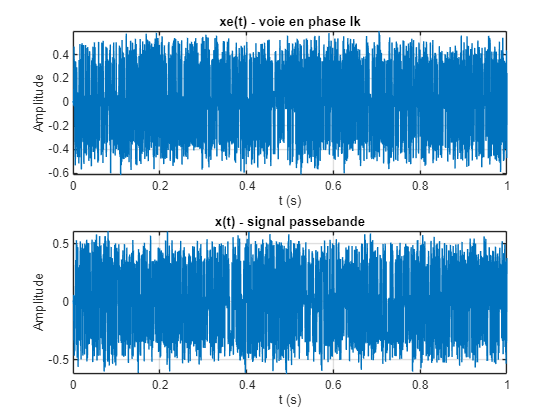

figure;
subplot(2,1,1);
plot(t_test, real(xe_test));
title('xe(t) - voie en phase Ik'); xlabel('t (s)'); ylabel('Amplitude'); grid on;xlim([0, 1]);

subplot(2,1,2);
plot(t_test, imag(xe_test));
title('xe(t) - voie en quadrature Qk'); xlabel('t (s)'); ylabel('Amplitude'); grid on;xlim([0, 1]);
title('x(t) - signal passebande'); xlabel('t (s)'); ylabel('Amplitude'); grid on;

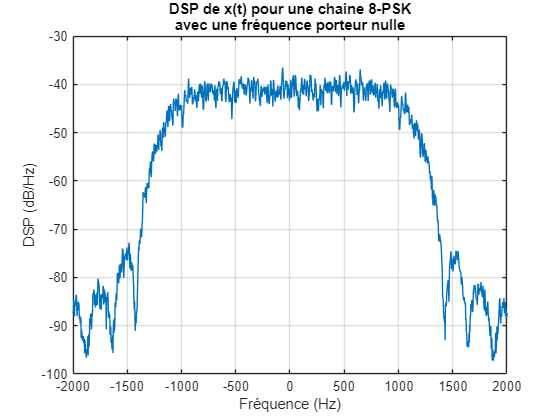

%% DSP de x(t)
figure;
[pxx, f] = pwelch(x_test, [], [], [], Fs, "centered");
plot(f, 10*log10(pxx));
title({'DSP de x(t) pour une chaine 8-PSK', 'avec une fréquence porteur nulle'}); xlabel('Fréquence (Hz)'); ylabel('DSP (dB/Hz)'); grid on;
xlim([-2000, 2000]);

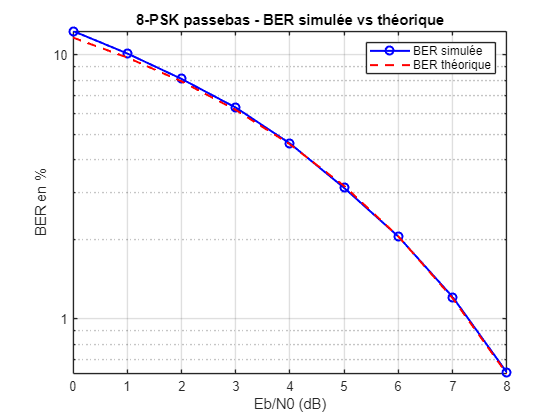

%% Tracé BER
figure;
semilogy(tab_EbN0_dB, BER_simu*100, 'bo-', 'LineWidth', 1.5, 'MarkerSize', 6); hold on;
semilogy(tab_EbN0_dB, BER_theo*100, 'r--', 'LineWidth', 1.5);
legend('BER simulée', 'BER théorique');
xlabel('Eb/N0 (dB)'); ylabel('BER en %');
title('8-PSK passebas - BER simulée vs théorique');
ytickformat('%.1f')
ax = gca;
ax.YTickLabel = string(ax.YTick);
grid on;

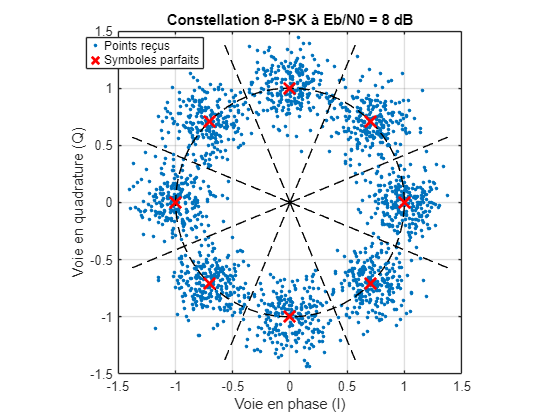

%% Affichage de la constellation 8-PSK
figure;

% 1. Tracer les points reçus (bruités)
% (Matlab comprend que r_echantillonne est complexe et met I en X et Q en Y)
plot(r_echantillonne, '.', 'MarkerSize', 8, 'DisplayName', 'Points reçus');
hold on;
grid on;

% 2. Tracer le cercle unitaire pour se repérer visuellement
theta = linspace(0, 2*pi, 100);
plot(cos(theta), sin(theta), 'k--', 'HandleVisibility', 'off');

% 3. Tracer les 8 symboles théoriques
gray_phases = [0, pi/4, 3*pi/4, pi/2, 7*pi/4, 3*pi/2, pi, 5*pi/4];
symboles_theoriques = exp(1j * gray_phases);
plot(real(symboles_theoriques), imag(symboles_theoriques), 'rx', 'MarkerSize', 12, 'LineWidth', 2, 'DisplayName', 'Symboles parfaits');

% 4. Tracer les frontières de décision (tous les 22.5° soit pi/8)
% On trace des lignes qui partent du centre (0,0) vers l'extérieur
for k = 0:7
    angle_frontiere = (pi/8) + k*(pi/4);
    % On trace jusqu'à un rayon de 1.5 pour bien voir la ligne
    x_line = [0, 1.5*cos(angle_frontiere)];
    y_line = [0, 1.5*sin(angle_frontiere)];
    plot(x_line, y_line, 'k--', 'HandleVisibility', 'off'); 
end

% 5. Mise en forme du graphique
title(['Constellation 8-PSK à Eb/N0 = ' num2str(EbN0_dB) ' dB']);
xlabel('Voie en phase (I)');
ylabel('Voie en quadrature (Q)');
legend('Location', 'best');

% Il est CRUCIAL de forcer des axes carrés, sinon le cercle sera un ovale
axis([-1.5 1.5 -1.5 1.5]); 
axis square; 
hold off;

## 16-QAM

#### en bande passante:

%% Paramètres
Fs= 12000;
Rb= 6000;
Fc= 2000;
alpha= 0.35;
M= 16;
Rs = Rb/log2(M); %débit de symbole
Ns= Fs/Rs;
span= 8;
nb_bits_block= 6000;%plus on mets un chiffre grand mieux le grap final suivera 
% le théorique par contre moins le graph des xe sera lisible au premier abord 
N= span*Ns +1; %TP1 modulateur 4

%% Filtre RRC p(t)
h= rcosdesign(alpha, span, Ns, 'sqrt');
t0= N;

%% Boucle BER
tab_EbN0_dB = [0:8];
BER_simu= zeros(1, length(tab_EbN0_dB));
BER_theo= zeros(1, length(tab_EbN0_dB));

for k = 1:length(tab_EbN0_dB)
    EbN0_dB  = tab_EbN0_dB(k);
    EbN0_lin = 10^(EbN0_dB/10);

    nb_erreurs=0;
    compteur=0;

    while nb_erreurs<5000

        %% Génération des bits
        bits = randi([0,1], 1, nb_bits_block);

        %% Mapping 16-QAM (2 bits pour I, 2 bits pour Q)
        bits_reshape = reshape(bits, log2(M), []).'; % On groupe par 4
        
        % Les 2 premiers bits pour la voie I (comme une 4-ASK)
        val_dec_I = bi2de(bits_reshape(:, 1:2), 'left-msb');
        % Les 2 derniers bits pour la voie Q (comme une 4-ASK)
        val_dec_Q = bi2de(bits_reshape(:, 3:4), 'left-msb');
        
        mapping_table = [-3, -1, 3, 1]; % Table Gray 4-ASK
        
        % On génère le symbole complexe : d_k = I_k + j*Q_k
        dk = mapping_table(val_dec_I + 1).' + 1j * mapping_table(val_dec_Q + 1).';
        
        % Stockage des bits pour comparaison futur
        symbole_binaire=bits_reshape;

        %% Oversampling:sum dk*delta(t - kTs)
        diracs=kron(dk.',[1 zeros(1, Ns-1)]);

        %% Pulse Shaping: xe(t)=sum dk*h(t-kTs)
        xe=filter(h,1,diracs);
        xe=xe(:).';

        %% Frequency translation : x(t) = Re[xe(t) * exp(j2pi*fc*t)]
        t_vect=(0:length(xe)-1)/Fs;
        x=real(xe.*exp(j*2*pi*Fc*t_vect));
        Px=mean(abs(x).^2);

        %% Canal AWGN : r(t) = x(t) + n(t)
        sigma_n=(Px*Ns)/(2*log2(M)*EbN0_lin);
        n= sqrt(sigma_n)*randn(1, length(x));
        r=x+n;

        %% Baseband translation :
        %  I : r(t)*cos(2pi*fc*t)
        %  Q : r(t)*(-j)*sin(2pi*fc*t)
        %  -> r(t)*exp(-j2pi*fc*t)
        r_bb =r.*exp(-j*2*pi*Fc*t_vect); % = 1/2*x_e
        r_bb = 2*r_bb;

        %% Reception filtering : filtre adapté p(t)
        r_filtre= filter(h, 1, r_bb);

        %% Sampling : échantillonnage à t0 + m*Ns
        r_echantillonne=r_filtre(t0:Ns:end);
        nb_symb= min(length(r_echantillonne), length(dk));
        % t0 fait perdre des valeurs 
        % donc il faut recalibré
        r_echantillonne= r_echantillonne(1:nb_symb);

        % Séparation des voies
        r_real = real(r_echantillonne);
        r_imag = imag(r_echantillonne);
        
        dk_decide = zeros(nb_symb, 4); % Matrice de 4 bits
        
        %% Décision sur la voie I (Bits 1 et 2)
        dk_decide(r_real > 0, 1) = 1;
        dk_decide(r_real > -2 & r_real < 2, 2) = 1;
        
        %% Décision sur la voie Q (Bits 3 et 4)
        dk_decide(r_imag > 0, 3) = 1;
        dk_decide(r_imag > -2 & r_imag < 2, 4) = 1;

        %% Demapping : symboles décidés -> bits
        nb_erreurs=nb_erreurs+sum(sum(symbole_binaire(1:nb_symb,:) ~= dk_decide));
        compteur=compteur+1;

    end

    BER_simu(k)=nb_erreurs/(compteur*nb_bits_block);
    BER_theo(k)=4/log2(M)*(1-1/sqrt(M))*1/2*erfc(sqrt( 3*log2(M)/(M-1)*EbN0_lin/2 ));

    fprintf('Eb/N0 = %d dB -> BER = %.2e (nb blocs = %d)\n', EbN0_dB, BER_simu(k), compteur);
end

Eb/N0 = 0 dB -> BER = 1.38e-01 (nb blocs = 7)
Eb/N0 = 1 dB -> BER = 1.19e-01 (nb blocs = 7)
Eb/N0 = 2 dB -> BER = 9.67e-02 (nb blocs = 9)
Eb/N0 = 3 dB -> BER = 7.82e-02 (nb blocs = 11)
Eb/N0 = 4 dB -> BER = 5.69e-02 (nb blocs = 15)
Eb/N0 = 5 dB -> BER = 4.18e-02 (nb blocs = 20)
Eb/N0 = 6 dB -> BER = 2.82e-02 (nb blocs = 30)
Eb/N0 = 7 dB -> BER = 1.74e-02 (nb blocs = 48)
Eb/N0 = 8 dB -> BER = 9.37e-03 (nb blocs = 89)



%% On refait mais sans le bruit
bits_reshape = reshape(bits, log2(M), []).';

% Les 2 premiers bits pour la voie I (comme une 4-ASK)
val_dec_I = bi2de(bits_reshape(:, 1:2), 'left-msb');
% Les 2 derniers bits pour la voie Q (comme une 4-ASK)
val_dec_Q = bi2de(bits_reshape(:, 3:4), 'left-msb');

mapping_table = [-3, -1, 3, 1]; % Table Gray 4-ASK

% On génère le symbole complexe : d_k = I_k + j*Q_k
dk_test = mapping_table(val_dec_I + 1).' + 1j * mapping_table(val_dec_Q + 1).';
symbole_binaire_test = bits_reshape;

diracs_test = kron(dk_test.', [1 zeros(1, Ns-1)]);
xe_test = filter(h, 1, diracs_test);
xe_test= xe_test(:).';
t_test= (0:length(xe_test)-1) / Fs;
x_test=real(xe_test.* exp(j*2*pi*Fc*t_test));

r_bb_test= x_test.*exp(-j*2*pi*Fc*t_test);
r_bb_test=2*r_bb_test;
r_filt_test= filter(h, 1, r_bb_test);
r_ech_test= r_filt_test(t0:Ns:end);
nb_symb_test= min(length(r_ech_test), length(dk_test));
r_ech_test= r_ech_test(1:nb_symb_test);

r_real_test = real(r_ech_test);
r_imag_test = imag(r_ech_test);

dk_decide_test = zeros(nb_symb, 4); % Matrice de 4 bits

%% Décision sur la voie I (Bits 1 et 2)
dk_decide_test(r_real_test > 0, 1) = 1;
dk_decide_test(r_real_test > -2 & r_real_test < 2, 2) = 1;

%% Décision sur la voie Q (Bits 3 et 4)
dk_decide_test(r_imag_test > 0, 3) = 1;
dk_decide_test(r_imag_test > -2 & r_imag_test < 2, 4) = 1;

BER_no_noise = sum(sum(symbole_binaire_test(1:nb_symb_test,:) ~= dk_decide_test)) / (nb_symb_test*2);
% le *2 est nécessaire pour avoir le nombre de bits
fprintf('BER sans bruit = %e (doit être 0)\n', BER_no_noise);

BER sans bruit = 0.000000e+00 (doit être 0)


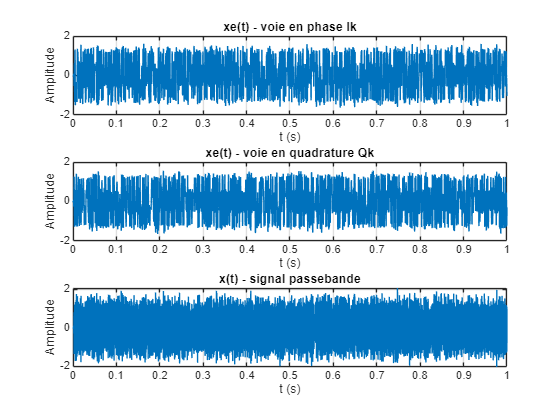

%% Plot signaux xe(t) et x(t)
figure;
subplot(3,1,1);
plot(t_test, real(xe_test));
title('xe(t) - voie en phase Ik'); xlabel('t (s)'); ylabel('Amplitude'); grid on;xlim([0, 1]);

subplot(3,1,2);
plot(t_test, imag(xe_test));
title('xe(t) - voie en quadrature Qk'); xlabel('t (s)'); ylabel('Amplitude'); grid on;xlim([0, 1]);

subplot(3,1,3);
plot(t_test, x_test);
title('x(t) - signal passebande'); xlabel('t (s)'); ylabel('Amplitude'); grid on;xlim([0, 1]);

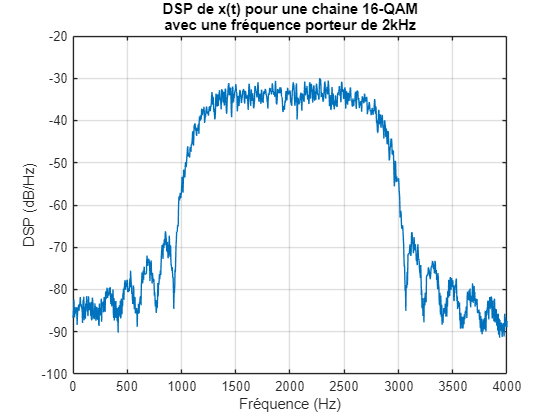

%% DSP de x(t)
figure;
[pxx, f] = pwelch(x_test, [], [], [], Fs);
plot(f, 10*log10(pxx));
title({'DSP de x(t) pour une chaine 16-QAM', 'avec une fréquence porteur de 2kHz'}); xlabel('Fréquence (Hz)'); ylabel('DSP (dB/Hz)'); grid on;
xlim([0, 4000]);

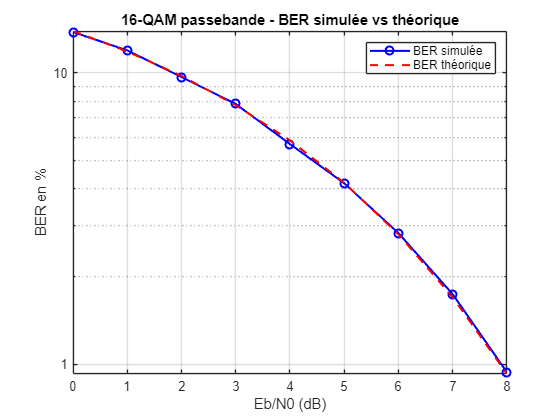

%% Tracé BER
figure;
semilogy(tab_EbN0_dB, BER_simu*100, 'bo-', 'LineWidth', 1.5, 'MarkerSize', 6); hold on;
semilogy(tab_EbN0_dB, BER_theo*100, 'r--', 'LineWidth', 1.5);
legend('BER simulée', 'BER théorique');
xlabel('Eb/N0 (dB)'); ylabel('BER en %');
title('16-QAM passebande - BER simulée vs théorique');
ytickformat('%.1f')
ax = gca;
ax.YTickLabel = string(ax.YTick);
grid on;

#### En passe bas:

BER_simu= zeros(1, length(tab_EbN0_dB));
BER_theo= zeros(1, length(tab_EbN0_dB));

for k = 1:length(tab_EbN0_dB)
    EbN0_dB  = tab_EbN0_dB(k);
    EbN0_lin = 10^(EbN0_dB/10);

    nb_erreurs=0;
    compteur=0;

    while nb_erreurs<5000

        %% Génération des bits
        bits = randi([0,1], 1, nb_bits_block);

        %% Mapping 16-QAM (2 bits pour I, 2 bits pour Q)
        bits_reshape = reshape(bits, log2(M), []).'; % On groupe par 4
        
        % Les 2 premiers bits pour la voie I (comme une 4-ASK)
        val_dec_I = bi2de(bits_reshape(:, 1:2), 'left-msb');
        % Les 2 derniers bits pour la voie Q (comme une 4-ASK)
        val_dec_Q = bi2de(bits_reshape(:, 3:4), 'left-msb');
        
        mapping_table = [-3, -1, 3, 1]; % Table Gray 4-ASK
        
        % On génère le symbole complexe : d_k = I_k + j*Q_k
        dk = mapping_table(val_dec_I + 1).' + 1j * mapping_table(val_dec_Q + 1).';
        
        % Stockage des bits pour comparaison futur
        symbole_binaire=bits_reshape;

        %% Oversampling:sum dk*delta(t - kTs)
        diracs=kron(dk.',[1 zeros(1, Ns-1)]);

        %% Pulse Shaping: xe(t)=sum dk*h(t-kTs)
        xe=filter(h,1,diracs);
        xe=xe(:).';

        %% Frequency translation : x(t) = Re[xe(t) * exp(j2pi*fc*t)]
        t_vect=(0:length(xe)-1)/Fs;
        Pxe=mean(abs(xe).^2);

        %% Canal AWGN : r(t) = x(t) + n(t)
        sigma_n=(Pxe*Ns)/(2*log2(M)*EbN0_lin);
        n_I= sqrt(sigma_n)*randn(1, length(xe));
        n_Q= sqrt(sigma_n)*randn(1, length(xe));
        r=xe+(n_I+1j*n_Q);

        %% Reception filtering : filtre adapté p(t)
        r_filtre= filter(h, 1, r);

        %% Sampling : échantillonnage à t0 + m*Ns
        r_echantillonne=r_filtre(t0:Ns:end);
        nb_symb= min(length(r_echantillonne), length(dk));
        % t0 fait perdre des valeurs 
        % donc il faut recalibré
        r_echantillonne= r_echantillonne(1:nb_symb);

        % Séparation des voies
        r_real = real(r_echantillonne);
        r_imag = imag(r_echantillonne);
        
        dk_decide = zeros(nb_symb, 4); % Matrice de 4 bits
        
        %% Décision sur la voie I (Bits 1 et 2)
        dk_decide(r_real > 0, 1) = 1;
        dk_decide(r_real > -2 & r_real < 2, 2) = 1;
        
        %% Décision sur la voie Q (Bits 3 et 4)
        dk_decide(r_imag > 0, 3) = 1;
        dk_decide(r_imag > -2 & r_imag < 2, 4) = 1;

        %% Demapping : symboles décidés -> bits
        nb_erreurs=nb_erreurs+sum(sum(symbole_binaire(1:nb_symb,:) ~= dk_decide));
        compteur=compteur+1;

    end

    BER_simu(k)=nb_erreurs/(compteur*nb_bits_block);
    BER_theo(k)=4/log2(M)*(1-1/sqrt(M))*1/2*erfc(sqrt( 3*log2(M)/(M-1)*EbN0_lin/2 ));

    fprintf('Eb/N0 = %d dB -> BER = %.2e (nb blocs = %d)\n', EbN0_dB, BER_simu(k), compteur);
end

Eb/N0 = 0 dB -> BER = 1.42e-01 (nb blocs = 6)
Eb/N0 = 1 dB -> BER = 1.19e-01 (nb blocs = 8)
Eb/N0 = 2 dB -> BER = 9.61e-02 (nb blocs = 9)
Eb/N0 = 3 dB -> BER = 7.49e-02 (nb blocs = 12)
Eb/N0 = 4 dB -> BER = 5.76e-02 (nb blocs = 15)
Eb/N0 = 5 dB -> BER = 4.15e-02 (nb blocs = 21)
Eb/N0 = 6 dB -> BER = 2.80e-02 (nb blocs = 30)
Eb/N0 = 7 dB -> BER = 1.69e-02 (nb blocs = 50)
Eb/N0 = 8 dB -> BER = 9.26e-03 (nb blocs = 90)




%% On refait mais sans le bruit
bits_reshape = reshape(bits, log2(M), []).';

% Les 2 premiers bits pour la voie I (comme une 4-ASK)
val_dec_I = bi2de(bits_reshape(:, 1:2), 'left-msb');
% Les 2 derniers bits pour la voie Q (comme une 4-ASK)
val_dec_Q = bi2de(bits_reshape(:, 3:4), 'left-msb');

mapping_table = [-3, -1, 3, 1]; % Table Gray 4-ASK

% On génère le symbole complexe : d_k = I_k + j*Q_k
dk_test = mapping_table(val_dec_I + 1).' + 1j * mapping_table(val_dec_Q + 1).';
symbole_binaire_test = bits_reshape;

diracs_test = kron(dk_test.', [1 zeros(1, Ns-1)]);
xe_test = filter(h, 1, diracs_test);
xe_test= xe_test(:).';
t_test= (0:length(xe_test)-1) / Fs;
x_test=xe_test;

r_filt_test= filter(h, 1, x_test);
r_ech_test= r_filt_test(t0:Ns:end);
nb_symb_test= min(length(r_ech_test), length(dk_test));
r_ech_test= r_ech_test(1:nb_symb_test);

r_real_test = real(r_ech_test);
r_imag_test = imag(r_ech_test);

dk_decide_test = zeros(nb_symb, 4); % Matrice de 4 bits

%% Décision sur la voie I (Bits 1 et 2)
dk_decide_test(r_real_test > 0, 1) = 1;
dk_decide_test(r_real_test > -2 & r_real_test < 2, 2) = 1;

%% Décision sur la voie Q (Bits 3 et 4)
dk_decide_test(r_imag_test > 0, 3) = 1;
dk_decide_test(r_imag_test > -2 & r_imag_test < 2, 4) = 1;

BER_no_noise = sum(sum(symbole_binaire_test(1:nb_symb_test,:) ~= dk_decide_test)) / (nb_symb_test*2);
% le *2 est nécessaire pour avoir le nombre de bits
fprintf('BER sans bruit = %e (doit être 0)\n', BER_no_noise);

BER sans bruit = 0.000000e+00 (doit être 0)


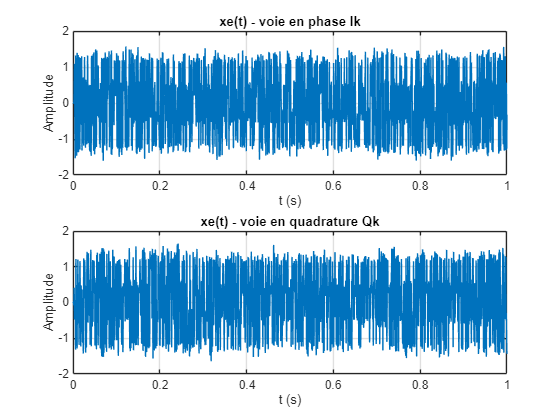


%% Plot signaux xe(t) et x(t)
figure;
subplot(2,1,1);
plot(t_test, real(xe_test));
title('xe(t) - voie en phase Ik'); xlabel('t (s)'); ylabel('Amplitude'); grid on;

subplot(2,1,2);
plot(t_test, imag(xe_test));
title('xe(t) - voie en quadrature Qk'); xlabel('t (s)'); ylabel('Amplitude'); grid on;

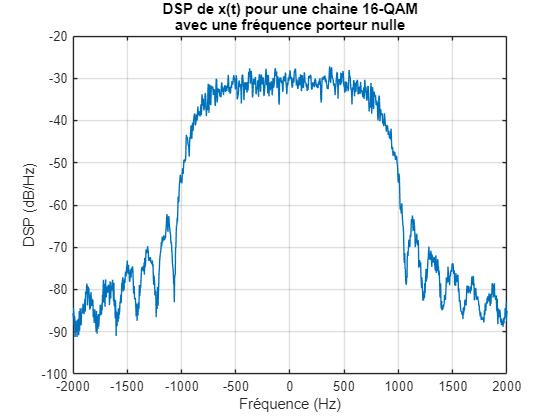

%% DSP de x(t)
figure;
[pxx, f] = pwelch(x_test, [], [], [], Fs, "centered");
plot(f, 10*log10(pxx));
title({'DSP de x(t) pour une chaine 16-QAM', 'avec une fréquence porteur nulle'}); xlabel('Fréquence (Hz)'); ylabel('DSP (dB/Hz)'); grid on;
xlim([-2000, 2000]);

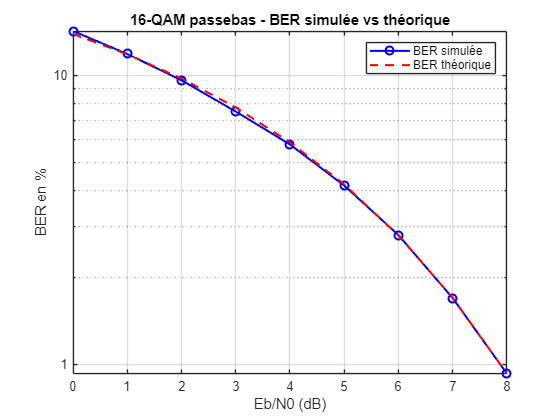

%% Tracé BER
figure;
semilogy(tab_EbN0_dB, BER_simu*100, 'bo-', 'LineWidth', 1.5, 'MarkerSize', 6); hold on;
semilogy(tab_EbN0_dB, BER_theo*100, 'r--', 'LineWidth', 1.5);
legend('BER simulée', 'BER théorique');
xlabel('Eb/N0 (dB)'); ylabel('BER en %');
title('16-QAM passebas - BER simulée vs théorique');
ytickformat('%.1f')
ax = gca;
ax.YTickLabel = string(ax.YTick);
grid on;

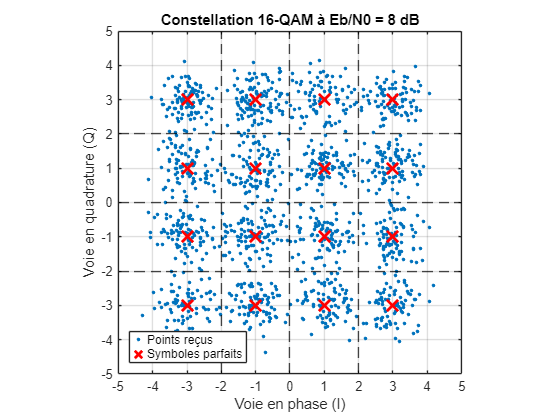

%% Affichage de la constellation 16-QAM
figure;

% 1. Tracer les points reçus (Bruités ou non)
plot(r_echantillonne, '.', 'MarkerSize', 8, 'DisplayName', 'Points reçus');
hold on;
grid on;

% 2. Tracer les 16 symboles théoriques
% On crée toutes les combinaisons possibles de [-3, -1, 1, 3] en I et Q
valeurs_1D = [-3, -1, 1, 3];
[I_grid, Q_grid] = meshgrid(valeurs_1D, valeurs_1D);
symboles_theoriques = I_grid + 1j * Q_grid;

plot(real(symboles_theoriques(:)), imag(symboles_theoriques(:)), 'rx', 'MarkerSize', 12, 'LineWidth', 2, 'DisplayName', 'Symboles parfaits');

% 3. Tracer les frontières de décision (Grille à -2, 0, 2)
frontieres = [-2, 0, 2];
for f = frontieres
    % Lignes verticales (Frontières de la voie I)
    xline(f, 'k--', 'HandleVisibility', 'off');
    % Lignes horizontales (Frontières de la voie Q)
    yline(f, 'k--', 'HandleVisibility', 'off');
end

% 4. Mise en forme du graphique
title(['Constellation 16-QAM à Eb/N0 = ' num2str(EbN0_dB) ' dB']);
xlabel('Voie en phase (I)');
ylabel('Voie en quadrature (Q)');
legend('Location', 'southwest');

% On cadre un peu plus large que les points extrêmes (+/- 3)
axis([-5 5 -5 5]); 
xticks(-5:1:5); 
yticks(-5:1:5);
axis square; 
hold off;